# -Assignment 1 - Tyre fitting-

Team 6: Consalvi Natale - Pettene Mattia - Zumerle Matteo

## --Initialization

define geometric data of tyre, import the path

clc;
close all;
clear;

set(0,'defaulttextinterpreter','latex')
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(0,'DefaultFigureWindowStyle','docked');
set(0,'defaultAxesFontSize',  16)
set(0,'DefaultLegendFontSize',16)

addpath('dataset/');
addpath('tyre_lib/');

% Tyre geometric data:
diameter = 18*2.56; %
Fz0 = 220;   % [N] nominal load
R0  = diameter/2/100; % [m] get from nominal load R0 (m)

% Constants for angle conversions
to_rad = pi/180;
to_deg = 180/pi;

data_set_path = 'dataset/';
last_fig_FX0 =0;

## --Initialization phase for tyre coefficients

tyre_coeffs_pl = initialise_tyre_data_ply(R0, Fz0);

## --Pure lateral force FY0: dataset import

data_set = 'Hoosier_B1464run23'; % pure lateral forces

fprintf('Loading dataset: ')

Loading dataset: 


switch data_set
  case 'Hoosier_B1464run23'
      fprintf('for pure lateral force analysis.')
      load ([data_set_path, data_set]); % pure lateral

  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

for pure lateral force analysis.


% select dataset portion (at the higher pressure)
cut_start_pl = 31350;
cut_end_pl   = 54500;


smpl_range_pl = cut_start_pl:cut_end_pl;

fprintf('\ncompleted!')


completed!

## ---Higher pressure dataset for pure lateral force: table selection and plot

consider the high pressure region of original dataset (more stable one)

vec_samples_pl = 1:1:length(smpl_range_pl);

tyre_data_pl = table();
% store raw data in table
tyre_data_pl.SL =  SL(smpl_range_pl);
tyre_data_pl.SA = -SA(smpl_range_pl)*to_rad;    % SAE -> Adapted SAE
tyre_data_pl.FZ = -FZ(smpl_range_pl);           % SAE -> Adapted SAE
tyre_data_pl.FX =  FX(smpl_range_pl);
tyre_data_pl.FY =  FY(smpl_range_pl);   
tyre_data_pl.MZ =  MZ(smpl_range_pl);
tyre_data_pl.IA =  IA(smpl_range_pl)*to_rad;

% Extract points at constant camber angle

% Test data done at: 
%  - 0 deg
%  - 1 deg
%  - 2 deg
%  - 3 deg
%  - 4 deg
% in the following order: (0 2 4 1 3)*2

GAMMA_tol_pl = 0.05*to_rad;
idx_pl.GAMMA_0 = 0.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 0.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_1 = 1.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 1.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_2 = 2.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 2.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_3 = 3.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 3.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_4 = 4.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 4.0*to_rad+GAMMA_tol_pl;

GAMMA_0_pl  = tyre_data_pl( idx_pl.GAMMA_0, : );
GAMMA_1_pl  = tyre_data_pl( idx_pl.GAMMA_1, : );
GAMMA_2_pl  = tyre_data_pl( idx_pl.GAMMA_2, : );
GAMMA_3_pl  = tyre_data_pl( idx_pl.GAMMA_3, : );
GAMMA_4_pl  = tyre_data_pl( idx_pl.GAMMA_4, : );

% Extract points at constant vertical load

% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 100lbf (100*0.453592*9.81 =  445N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )
% in the following order: (200 150 50 250 100)*2

FZ_tol_pl = 100;
idx_pl.FZ_220  = 220-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 220+FZ_tol_pl;
idx_pl.FZ_440  = 440-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 440+FZ_tol_pl;
idx_pl.FZ_700  = 700-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 700+FZ_tol_pl;
idx_pl.FZ_900  = 900-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 900+FZ_tol_pl;
idx_pl.FZ_1120 = 1120-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 1120+FZ_tol_pl;
FZ_220_pl  = tyre_data_pl( idx_pl.FZ_220, : );
FZ_440_pl  = tyre_data_pl( idx_pl.FZ_440, : );
FZ_700_pl  = tyre_data_pl( idx_pl.FZ_700, : );
FZ_900_pl  = tyre_data_pl( idx_pl.FZ_900, : );
FZ_1120_pl = tyre_data_pl( idx_pl.FZ_1120, : );

## ---FY0: fitting in pure conditions (gamma = 0, Fz = 220N)

choose the range with: longitudinal slip = 0, camber angle = 0, vertical load = Fz = 220N (obv within the higher pressure dataset)

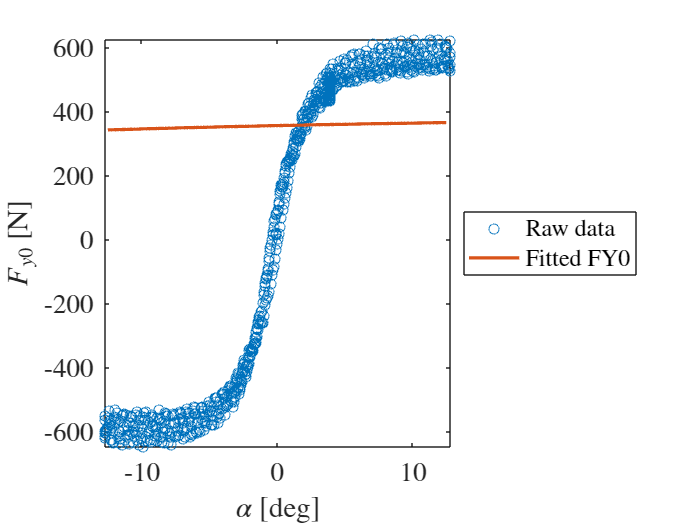

[TData0_pl, ~] = intersect_table_data( GAMMA_0_pl, FZ_220_pl );

% Fit the coefficients {pCy1, pDy1, pEy1, pHy1, pKy1, pKy2, pVy1}

zeros_vec_pl = zeros(size(TData0_pl.SA));
ones_vec_pl  = ones(size(TData0_pl.SA));

% Initial guess (import from initialization of tyre_coeffs)
[FY0_guess,~] = MF96_FY0_vec(zeros_vec_pl, TData0_pl.SA , zeros_vec_pl, tyre_coeffs_pl.FZ0*ones_vec_pl, tyre_coeffs_pl);

% % Check lateral pure force guess
% figure('Name','FY0: guess', 'NumberTitle', 4 + last_fig_FX0)
% plot(TData0_pl.SA*to_deg,TData0_pl.FY,'.')
% hold on
% plot(TData0_pl.SA*to_deg,FY0_guess,'.')
% hold off
% legend({'Raw data','Guess FY0'}, 'Location','eastoutside');
% xlabel('$\alpha$ [deg]')
% ylabel('$F_{y0}$ [N]')

% Guess values for parameters to be optimised
%       [pCy1 pDy1 pEy1 pHy1  pKy1  pKy2  pVy1]
% P0_pl = [ 1, 1,	1,	1,	1,	1,	1 ]; 
% 
% % Limits for parameters to be optimised
% lb_pl = [ ];
% ub_pl = [ ];
% 
% ALPHA_vec = TData0_pl.SA;
% FY_vec    = TData0_pl.FY;
% 
% % Vector for plotting: Side slip vector from -12.5° to 12.5°
SA_vec = (-12.5*to_rad):0.001:(12.5*to_rad);
% 
% % Minimization of the residual
% [P_fz_nom_pl,fval,exitflag] = fmincon(@(P)resid_pure_Fy(P,FY_vec, ALPHA_vec,0,mean(TData0_pl.FZ), tyre_coeffs_pl),...
%                                P0_pl,[],[],[],[],lb_pl,ub_pl);

% Update tyre data with new optimal values                            
% tyre_coeffs_pl.pCy1 = P_fz_nom_pl(1) ;
% tyre_coeffs_pl.pDy1 = P_fz_nom_pl(2) ;  
% tyre_coeffs_pl.pEy1 = P_fz_nom_pl(3) ;
% tyre_coeffs_pl.pHy1 = P_fz_nom_pl(4) ;
% tyre_coeffs_pl.pKy1 = P_fz_nom_pl(5) ; 
% tyre_coeffs_pl.pKy2 = P_fz_nom_pl(6) ;
% tyre_coeffs_pl.pVy1 = P_fz_nom_pl(7) ;
tyre_coeffs_pl.pCy1 = 1;
tyre_coeffs_pl.pDy1 = 1;
tyre_coeffs_pl.pEy1 = 1;
tyre_coeffs_pl.pHy1 = 1;
tyre_coeffs_pl.pKy1 = 1;
tyre_coeffs_pl.pKy2 = 1;
tyre_coeffs_pl.pVy1 = 1;

% res_FY0 = resid_pure_Fy(P_fz_nom_pl , FY_vec, SA_vec, 0 , mean(TData0_pl.FZ), tyre_coeffs_pl);


% Plot of the optimized solution
[FY0_fz_nom_vec,~] = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec , zeros(size(SA_vec)), ...
                              mean(TData0_pl.FZ).*ones(size(SA_vec)),tyre_coeffs_pl);

% Result of the fitting FY0 in the pure conditions
figure('Name','FY0: fitted in pure conditions','NumberTitle', 5 + last_fig_FX0)
plot(TData0_pl.SA*to_deg,TData0_pl.FY,'o')
hold on
plot(SA_vec*to_deg,FY0_fz_nom_vec,'-','LineWidth',2)
legend({'Raw data','Fitted FY0'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}$ [N]')

## ---FY0(Fz): fitting with variable Fz

extract data with variable load and camber angle equal to 0

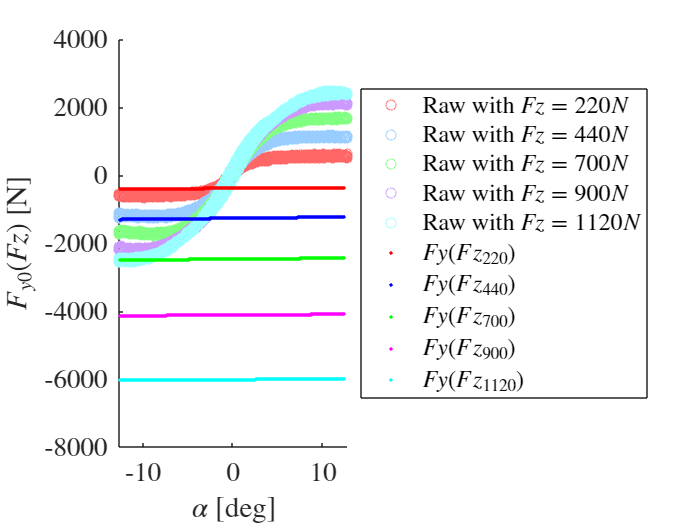

TDataDFz_pl = GAMMA_0_pl;

% figure('Name','Variable Fz range', 'NumberTitle', 6 + last_fig_FX0)
% plot_selected_data(TDataDFz);

smpl_range_pl_dFz = size(TDataDFz_pl);
vec_samples_pl_dFz = 1:1:smpl_range_pl_dFz;

% Extract points at constant vertical load
FZ_tol_pl_dFz = 100;
idx_pl_dFz.FZ_220  = 220-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 220+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_440  = 440-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 440+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_700  = 700-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 700+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_900  = 900-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 900+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_1120 = 1120-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 1120+FZ_tol_pl_dFz;
FZ_220_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_220, : );
FZ_440_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_440, : );
FZ_700_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_700, : );
FZ_900_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_900, : );
FZ_1120_pl_dFz = TDataDFz_pl( idx_pl_dFz.FZ_1120, : );


zeros_vec_pl = zeros(size(TDataDFz_pl.SA));
ones_vec_pl  = ones(size(TDataDFz_pl.SA));

% Guess values for parameters to be optimised
%    [pDy2 pEy2 pHy2 pVy2] 
% P0_pl_dFz =[ 0, 0, 0, 0 ];   
% 
% % Limits for parameters to be optimised
% %    [pDy2 pEy2 pHy2 pVy2] 
% lb_dFz = [ ];
% ub_dFz = [ ];

ALPHA_vec_dFz = TDataDFz_pl.SA;
FY_vec_dFz    = TDataDFz_pl.FY;
FZ_vec_dFz    = TDataDFz_pl.FZ;

% % check guess for variable load
% [FY0_dfz_vec,~] = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
%                               mean(FZ_220_pl_dFz.FZ)*ones(size(SA_vec)),tyre_coeffs_pl);
% 
% figure('Name','FY0(Fz): guess', 'NumberTitle', 7 + last_fig_FX0)
% plot(ALPHA_vec_dFz*to_deg,FY_vec_dFz,'.')
% hold on
% plot(SA_vec*to_deg,FY0_dfz_vec,'.')
% legend({'Raw data variable load','Guess FY0'}, 'Location','eastoutside');
% xlabel('$\alpha$ [deg]')
% ylabel('$F_{y0}(Fz)$ [N]')

% % Resitual minimization
% [P_dfz_pl,fval,exitflag] = fmincon(@(P_pl)resid_pure_Fy_varFz(P_pl,FY_vec_dFz, ALPHA_vec_dFz,0,FZ_vec_dFz, tyre_coeffs_pl),...
%                                P0_pl_dFz,[],[],[],[],lb_dFz,ub_dFz);

% Change tyre data with new optimal values                             
%tyre_coeffs_pl.pDy2 = P_dfz_pl(1);
tyre_coeffs_pl.pDy2 = -1;
%tyre_coeffs_pl.pEy2 = P_dfz_pl(2);
tyre_coeffs_pl.pEy2 = -1;
%tyre_coeffs_pl.pHy2 = P_dfz_pl(3);
tyre_coeffs_pl.pHy2 = -1;
% tyre_coeffs_pl.pVy2 = P_dfz_pl(4);
tyre_coeffs_pl.pVy2 = -1;
% 
% res_FY0_dfz = resid_pure_Fy_varFz(P_dfz_pl , FY_vec_dFz,SA_vec, 0 , FZ_vec_dFz, tyre_coeffs_pl);

tmp_zeros_dFz = zeros(size(SA_vec));
tmp_ones_dFz = ones(size(SA_vec));

[FY0_fz_var_vec1, Kya_fz_var_vec1] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_220_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec2, Kya_fz_var_vec2] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_440_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec3, Kya_fz_var_vec3] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_700_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec4, Kya_fz_var_vec4] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_900_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec5, Kya_fz_var_vec5] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_1120_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);


figure('Name','FY0(Fz): fitted with variable Fz','NumberTitle', 8 + last_fig_FX0)
hold on
plot(FZ_220_pl_dFz.SA*to_deg,FZ_220_pl_dFz.FY,'o', 'Color', [1 0.4 0.4])
plot(FZ_440_pl_dFz.SA*to_deg,FZ_440_pl_dFz.FY,'o', 'Color', [0.6 0.8 1])
plot(FZ_700_pl_dFz.SA*to_deg,FZ_700_pl_dFz.FY,'o', 'Color', [0.5 1 0.5])
plot(FZ_900_pl_dFz.SA*to_deg,FZ_900_pl_dFz.FY,'o', 'Color', [0.8 0.6 1])
plot(FZ_1120_pl_dFz.SA*to_deg,FZ_1120_pl_dFz.FY,'o', 'Color', [0.6 1 1])
plot(SA_vec*to_deg,FY0_fz_var_vec1,'.','LineWidth',2, 'Color', 'r')
plot(SA_vec*to_deg,FY0_fz_var_vec2,'.','LineWidth',2, 'Color', 'b')
plot(SA_vec*to_deg,FY0_fz_var_vec3,'.','LineWidth',2, 'Color', 'g')
plot(SA_vec*to_deg,FY0_fz_var_vec4,'.','LineWidth',2, 'Color', 'm')
plot(SA_vec*to_deg,FY0_fz_var_vec5,'.','LineWidth',2, 'Color', 'c')
hold off
legend({'Raw with $Fz=220N$','Raw with $Fz=440N$','Raw with $Fz=700N$','Raw with $Fz=900N$','Raw with $Fz=1120N$', '$Fy(Fz_{220})$','$Fy(Fz_{440})$','$Fy(Fz_{700})$','$Fy(Fz_{900})$','$Fy(Fz_{1120})$'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}(Fz)$ [N]')

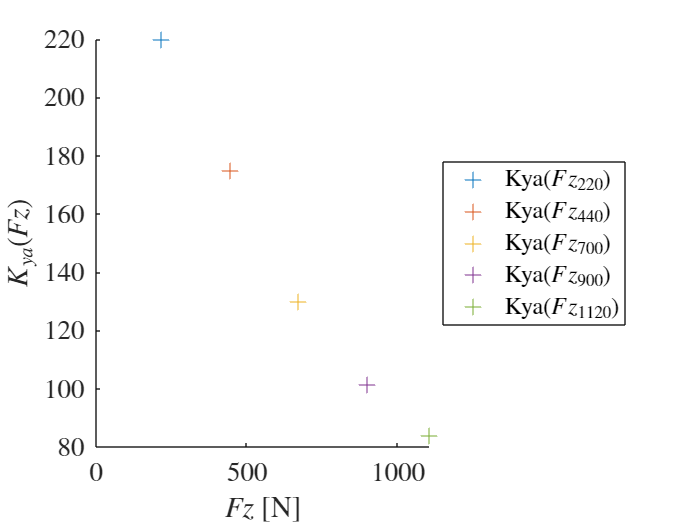


% Stiffness
figure('Name','Kya(Fz): cornering stiffness as function of Fz','NumberTitle', 9 + last_fig_FX0)
hold on
plot(mean(FZ_220_pl_dFz.FZ),Kya_fz_var_vec1(1),'+','MarkerSize',10)
plot(mean(FZ_440_pl_dFz.FZ),Kya_fz_var_vec2(1),'+','MarkerSize',10)
plot(mean(FZ_700_pl_dFz.FZ),Kya_fz_var_vec3(1),'+','MarkerSize',10)
plot(mean(FZ_900_pl_dFz.FZ),Kya_fz_var_vec4(1),'+','MarkerSize',10)
plot(mean(FZ_1120_pl_dFz.FZ),Kya_fz_var_vec5(1),'+','MarkerSize',10)
hold off
legend({'Kya($Fz_{220}$)','Kya($Fz_{440}$)','Kya($Fz_{700}$)','Kya($Fz_{900}$)','Kya($Fz_{1120}$)'}, 'Location','eastoutside');
xlabel('$Fz$ [N]')
ylabel('$K_{ya}(Fz)$')

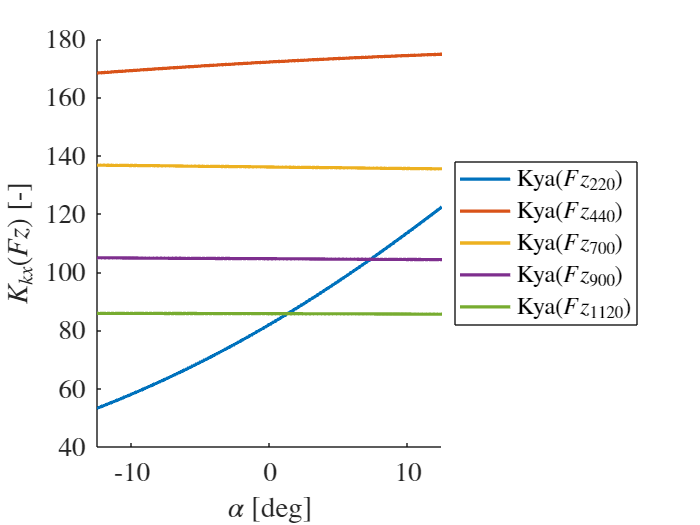


Calfa_vec1_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_220_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec2_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_440_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec3_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_700_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec4_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_900_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec5_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_1120_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);

figure('Name','Kya(alpha): cornering stiffness as function of alpha','NumberTitle', 10 + last_fig_FX0)
hold on
plot(SA_vec*to_deg,Calfa_vec1_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec2_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec3_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec4_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec5_y,'-','LineWidth',2)
hold off
legend({'Kya($Fz_{220}$)','Kya($Fz_{440}$)','Kya($Fz_{700}$)','Kya($Fz_{900}$)','Kya($Fz_{1120}$)'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$K_{kx}(Fz)$ [-]')

## ---FY0(gamma): fitting with variable camber(gamma)

extract data with the same vertical load (Fz = 220N) 

% TDataGamma_pl = FZ_220_pl;
% 
% smpl_range_pl_dgamma = size(TDataGamma_pl);
% vec_samples_pl_dgamma = 1:1:smpl_range_pl_dgamma;
% 
% % Extract points at constant camber
% GAMMA_tol_pl_dgamma = 0.05*to_rad;
% idx_pl_dgamma.GAMMA_0 = 0.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 0.0*to_rad+GAMMA_tol_pl_dgamma;
% idx_pl_dgamma.GAMMA_1 = 1.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 1.0*to_rad+GAMMA_tol_pl_dgamma;
% idx_pl_dgamma.GAMMA_2 = 2.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 2.0*to_rad+GAMMA_tol_pl_dgamma;
% idx_pl_dgamma.GAMMA_3 = 3.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 3.0*to_rad+GAMMA_tol_pl_dgamma;
% idx_pl_dgamma.GAMMA_4 = 4.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 4.0*to_rad+GAMMA_tol_pl_dgamma;
% 
% GAMMA_0_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_0, : );
% GAMMA_1_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_1, : );
% GAMMA_2_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_2, : );
% GAMMA_3_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_3, : );
% GAMMA_4_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_4, : );
% 
% % Plot
% figure('Name','FY0(gamma): considered dataset', 'NumberTitle', 11 + last_fig_FX0)
% tiledlayout(3,1)
% ax_list_4(1) = nexttile;
% plot(TDataGamma_pl.IA*to_deg)
% hold on
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_0),GAMMA_0_dgamma.IA*to_deg,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_1),GAMMA_1_dgamma.IA*to_deg,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_2),GAMMA_2_dgamma.IA*to_deg,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_3),GAMMA_3_dgamma.IA*to_deg,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_4),GAMMA_4_dgamma.IA*to_deg,'.');
% title('Camber angle')
% xlabel('Samples [-]')
% ylabel('[deg]')
% hold off
% 
% ax_list_4(2) = nexttile;
% plot(TDataGamma_pl.FY)
% hold on
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_0),GAMMA_0_dgamma.FY,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_1),GAMMA_1_dgamma.FY,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_2),GAMMA_2_dgamma.FY,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_3),GAMMA_3_dgamma.FY,'.');
% plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_4),GAMMA_4_dgamma.FY,'.');
% title('Lateral force')
% xlabel('Samples [-]')
% ylabel('[N]')
% hold off
% 
% ax_list_4(3) = nexttile;
% plot(TDataGamma_pl.FZ)
% title('Vertical force')
% xlabel('Samples [-]')
% ylabel('[N]')
% linkaxes(ax_list_4,'x')
% 
% % Fit the coeffs {pDy3, pEy3, pEy4, pHy3, pKy3, pVy3, pVy4}
% 
% % Guess values for parameters to be optimised
% %   [pDy3, pEy3, pEy4, pHy3, pKy3, pVy3, pVy4]
% % P0_pl_dgamma = [ 0.51e1 , 1.88 , -0.42e1 , -2.04 , 0.13e1 , -0.29e1 , -0.28e1 ];
% % 
% % % Limits for parameters to be optimised
% % lb_dgamma = [5,1,-100,-2.5,0,-100,-100];
% % ub_dgamma = [100,100,0,-0.1,100,0,0];
% 
% zeros_vec_dgamma = zeros(size(TDataGamma_pl.IA));
% ones_vec_dgamma  = ones(size(TDataGamma_pl.IA));
% 
% ALPHA_vec_dgamma = TDataGamma_pl.SA; 
% GAMMA_vec_dgamma = TDataGamma_pl.IA; 
% FY_vec_dgamma    = TDataGamma_pl.FY;
% FZ_vec_dgamma    = TDataGamma_pl.FZ;
% 
% [FY0_varGamma_vec,~] = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec , GAMMA_vec_dgamma, tyre_coeffs_pl.FZ0*ones(size(SA_vec)),tyre_coeffs_pl);
% 
% figure('Name','FY0(gamma): guess', 'NumberTitle', 12 + last_fig_FX0)
% plot(ALPHA_vec_dgamma,TDataGamma_pl.FY,'o')
% hold on
% plot(SA_vec,FY0_varGamma_vec,'.','MarkerSize',5)
% legend({'Raw data variable camber','Guess FY0(gamma)'}, 'Location','eastoutside');
% xlabel('$\alpha$ [deg]')
% ylabel('$F_{y0}(\gamma)$ [N]')
% 
% % Residual minimization
% [P_varGamma,fval,exitflag] = fmincon(@(P)resid_pure_Fy_varGamma(P,FY_vec_dgamma, ALPHA_vec_dgamma,GAMMA_vec_dgamma,tyre_coeffs_pl.FZ0, tyre_coeffs_pl),...
%                                P0_pl_dgamma,[],[],[],[],lb_dgamma,ub_dgamma);
% 
% % Change tyre data with new optimal values                             
% tyre_coeffs_pl.pDy3 = P_varGamma(1);  
% tyre_coeffs_pl.pEy3 = P_varGamma(2); 
% tyre_coeffs_pl.pEy4 = P_varGamma(3); 
% tyre_coeffs_pl.pHy3 = P_varGamma(4); 
% tyre_coeffs_pl.pKy3 = P_varGamma(5); 
% tyre_coeffs_pl.pVy3 = P_varGamma(6); 
% tyre_coeffs_pl.pVy4 = P_varGamma(7); 
% 
% tmp_zeros_dgamma = zeros(size(SA_vec));
% tmp_ones_dgamma = ones(size(SA_vec));
% 
% [FY0_gamma_var_vec1,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_0_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
% [FY0_gamma_var_vec2,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_1_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
% [FY0_gamma_var_vec3,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_2_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
% [FY0_gamma_var_vec4,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_3_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
% [FY0_gamma_var_vec5,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_4_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
% 
% 
% figure('Name','FY0(gamma): fitted with variable camber','NumberTitle', 13 + last_fig_FX0)
% hold on
% plot(GAMMA_0_dgamma.SA*to_deg,GAMMA_0_dgamma.FY,'-','MarkerSize',5, 'Color', '#0072BD') %'MarkerEdgeColor','y',
% plot(GAMMA_1_dgamma.SA*to_deg,GAMMA_1_dgamma.FY,'-','MarkerSize',5, 'Color', '#D95319') %'MarkerEdgeColor','c',
% plot(GAMMA_2_dgamma.SA*to_deg,GAMMA_2_dgamma.FY,'-','MarkerSize',5, 'Color', '#EDB120') %'MarkerEdgeColor','m',
% plot(GAMMA_3_dgamma.SA*to_deg,GAMMA_3_dgamma.FY,'-','MarkerSize',5, 'Color', '#77AC30') %'MarkerEdgeColor','b',
% plot(GAMMA_4_dgamma.SA*to_deg,GAMMA_4_dgamma.FY,'-','MarkerSize',5, 'Color', '#4DBEEE') %'MarkerEdgeColor','r',
% plot(SA_vec*to_deg,FY0_gamma_var_vec1,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#0072BD')
% plot(SA_vec*to_deg,FY0_gamma_var_vec2,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#D95319')
% plot(SA_vec*to_deg,FY0_gamma_var_vec3,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#EDB120')
% plot(SA_vec*to_deg,FY0_gamma_var_vec4,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#77AC30')
% plot(SA_vec*to_deg,FY0_gamma_var_vec5,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#4DBEEE')
% legend({'Raw data with $\gamma = 0 deg $','Raw data with $\gamma = 1 deg $','Raw data with $\gamma = 2 deg $','Raw data with $\gamma = 3 deg $','Raw data with $\gamma = 4 deg $', 'Fy($\gamma = 0 deg$)','Fy($\gamma = 1 deg$)','Fy($\gamma = 2 deg$)','Fy($\gamma = 3 deg$)','Fy($\gamma = 4 deg$)'}, 'Location','eastoutside');
% xlabel('$\alpha$ [deg]')
% ylabel('$F_{y0}(\gamma)$ [N]')
% 
% % Calculate the residuals with the optimal solution found above
% res_Fy0_dgamma  = resid_pure_Fy_varGamma(P_varGamma,FY_vec_dgamma, ALPHA_vec_dgamma,GAMMA_vec_dgamma,tyre_coeffs_pl.FZ0, tyre_coeffs_pl);
% 
% % % R-squared is 
% % % 1-SSE/SST
% % % SSE/SST = res_Fx0_nom
% % 
% % % SSE is the sum of squared error,  SST is the sum of squared total
% % fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);
% % 
% % 
% % [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, GAMMA_vec_dgamma(3), tyre_coeffs.FZ0, tyre_coeffs);
% % % 
% % fprintf('Bx      = %6.3f\n',Bx);
% % fprintf('Cx      = %6.3f\n',Cx);
% % fprintf('mux      = %6.3f\n',Dx/tyre_coeffs.FZ0);
% % fprintf('Ex      = %6.3f\n',Ex);
% % fprintf('SVx     = %6.3f\n',SVx);
% % fprintf('kappa_x = %6.3f\n',kappa__x);
% % fprintf('Kx      = %6.3f\n',Bx*Cx*Dx/tyre_coeffs.FZ0);
% 
% % % Longitudinal stiffness
% % Kx_vec = zeros(size(load_vec));
% % for i = 1:length(load_vec)
% %   [kappa__x, Bx, Cx, Dx, Ex, SVx] = MF96_FX0_coeffs(0, 0, 0, load_vec(i), tyre_data);
% %   Kx_vec(i) = Bx*Cx*Dx/tyre_data.Fz0;
% % end
% % 
% % figure('Name','Kx vs Fz')
% % plot(load_vec,Kx_vec,'o-')

## ---------------last figure FY0---------------

% last_fig_FY0 = 13 + last_fig_FX0;